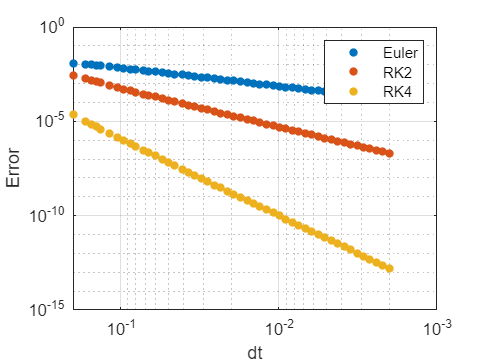

clc;clear;
close all

% Defining the function:
f = @(lambda,x)(lambda*x);

%Simulation parameters:
lambda = -2;
tFinal = 2;
deltaT=0.1;

% The exact Solution:
tExact = 0:0.01:tFinal;
x0=1;
xExact = x0*exp(lambda*tExact);


N_table = floor(logspace(1,3,50));

for index = 1:length(N_table)
    N = N_table(index);
    dt(index) = tFinal / N_table(index);
    t = zeros(N,1);
    xEuler = zeros(N,1);
    xRK2 = zeros(N,1);
    xRK4 = zeros(N,1);


    for j = 2:N+1
        t(j) = t(j-1) + dt(index);
        
        %Using explicit Euler
        ButcherEuler=butchert(1);
        xEuler(1)=1;
        xEuler(j) = xEuler(j-1) + ButcherEuler(2,2)*dt(index)*f(lambda, xEuler(j-1));
        

        %Using explicit RK2
        ButcherRK2=butchert(2);
        a21=ButcherRK2(2,2);
        c2=ButcherRK2(2,1); 
        b2_RK2=ButcherRK2(3,3);
        xRK2(1)=1;
        
        K1_RK2 = f(lambda, xRK2(j-1));
        K2_RK2 = f(lambda, xRK2(j-1)+a21*dt(index)*K1_RK2);
        xRK2(j) = xRK2(j-1) + dt(index)*(b2_RK2*K2_RK2) ;
        

        %Using explicit RK4
        ButcherRK4=butchert(4);
        a33=ButcherRK4(3,3);
        a44=ButcherRK4(4,4);
        b=ButcherRK4(5,2:end)';
        xRK4(1)=1;
        
        K1_RK4 = f(lambda, xRK4(j-1));
        K2_RK4 = f(lambda, xRK4(j-1)+a21*dt(index)*K1_RK4);
        K3 = f(lambda, xRK4(j-1)+a33*dt(index)*K2_RK4);
        K4 = f(lambda, xRK4(j-1)+a44*dt(index)*K3);
        xRK4(j) = xRK4(j-1) + dt(index)*(b(1)*K1_RK4+ b(2)*K2_RK4+b(3)*K3+b(4)*K4);
        
    end
    err(1,index) = norm(xEuler(end)-xExact(end),inf);
    err(2,index) = norm(xRK2(end)-xExact(end),inf);
    err(3,index) = norm(xRK4(end)-xExact(end),inf);
end

figure(1);clf; 
loglog(dt,err,'marker','.','markersize',15,'linestyle','none')
grid on
set(gca,'XDir','reverse')
legend('Euler', 'RK2', 'RK4')
xlabel('dt')
ylabel('Error')

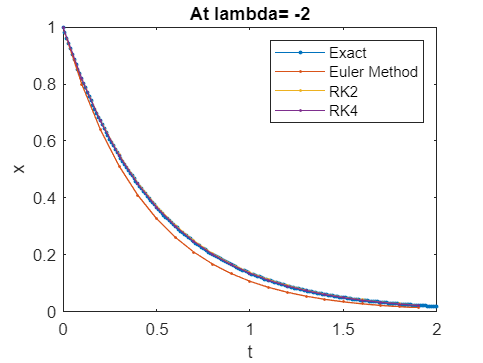

%Stability
lambda1=-2;
xExact_s = x0*exp(lambda1*tExact);


tFinal = 2;
deltaT= 0.1;
Nsteps=tFinal/deltaT;
xEuler_s = zeros(Nsteps,1);
xRK2_s = zeros(Nsteps,1);
xRK4_s = zeros(Nsteps,1);
t_s=zeros(Nsteps,1);
for s=2:Nsteps
    t_s(s) = t_s(s-1) + deltaT;
    xEuler_s(1)=1;
    xEuler_s(s) = xEuler_s(s-1) + ButcherEuler(2,2)*deltaT*f(lambda1, xEuler_s(s-1));
    
    ButcherRK2=butchert(2);
    a21=ButcherRK2(2,2);
    c2=ButcherRK2(2,1); 
    b2_RK2=ButcherRK2(3,3);
    xRK2_s(1)=1;
    K1_RK2_s = f(lambda1, xRK2_s(s-1));
    K2_RK2_s = f(lambda1, xRK2_s(s-1)+a21*deltaT*K1_RK2_s);
    xRK2_s(s) = xRK2_s(s-1) + deltaT*(b2_RK2*K2_RK2_s);
    
    xRK4_s(1)=1;
    K1_RK4_s = f(lambda1, xRK4_s(s-1));
    K2_RK4_s = f(lambda1, xRK4_s(s-1)+a21*deltaT*K1_RK4_s);
    K3_s = f(lambda1, xRK4_s(s-1)+a33*deltaT*K2_RK4_s);
    K4_s = f(lambda1, xRK4_s(s-1)+a44*deltaT*K3_s);
    xRK4_s(s) = xRK4_s(s-1) + deltaT*(b(1)*K1_RK4_s+ b(2)*K2_RK4_s+b(3)*K3_s+b(4)*K4_s); 
end

clf
plot(tExact,xExact_s,'marker','.','markersize',7)
hold on
plot(t_s,xEuler_s,'marker','.','markersize',5)
plot(t_s,xRK2_s,'marker','.','markersize',5)
plot(t_s,xRK4_s,'marker','.','markersize',5)
xlabel('t');
ylabel('x');
legend('Exact','Euler Method','RK2','RK4')
title(['At lambda= ',num2str(lambda1)])
%ylim([-10 10])
hold off

% syms lambda_euler lambda_RK2 lambda_RK4
% OrderEuler=1;
% OrderRK2=2;
% OrderRK4=4;
% 
% for k1 =0 : OrderEuler
%     Euler_stab(k1+1)= (lambda_euler*deltaT)^k1/factorial(k1);
%     Euler_stability=abs(sum(Euler_stab));
% end
% s_euler=solve([Euler_stability Euler_stability<=1 real(lambda_euler)<0],lambda_euler,'ReturnConditions',true)
% 
% for k2 =0 : OrderRK2
%     RK2_stab(k2+1)= (lambda_RK2*deltaT)^k2/factorial(k2);
%     RK2_stability=abs(sum(RK2_stab));
% end
% s_RK2=solve([RK2_stability RK2_stability<=1 real(lambda_RK2)<0],lambda_RK2,'ReturnConditions',true)
% 
% 
% for k4 =0 : OrderRK4
%     RK4_stab(k4+1)= (lambda_RK4*deltaT)^k4/factorial(k4);
%     RK4_stability=abs(sum(RK4_stab));
% end
% s_RK4=solve([RK4_stability RK4_stability<=1 real(lambda_RK4)<0],lambda_RK4,'ReturnConditions',true)